## Tutorial 4: Two step optimization part one: the cell finding module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a two-photon calcium imaging movie collected following the published guidelines, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information on the imaging and experimental conditions.

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Watching the preprocessed movie

As the first step, we watch the preprocessed movie and ensure that the motion is properly corrected and the spatial filtering does not introduce significant artifacts.

M = single(h5read("D:\W2_DATA\kbarber\2025_03_01\mk301\assembled\plane_7.h5", "/mov"));
config = get_defaults([]);
M_proc = preprocess_movie(M,config);
% % view_movie(M_proc(:,:,1:100))

From watching the preprocessed movie, it is rather clear that we are aiming to perform cell extraction from a rather low SNR movie, in which the cells are barely visible to the eye. Thus, cell finding module likely needs to be tweaked to account for this fact.

### Cell extraction with defaults

We start with a simple cell extraction using mainly the default parameters.

config = get_defaults([]);
config.downsample_time_by = 4;
config.use_gpu = 0;
output = extractor(M,config);

01-Apr-2025 15:26:54: Signal extraction will run on 1 partitions serially... 
01-Apr-2025 15:26:54: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 


plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])
% drawnow

As expected, the cell extraction with default values missed several cells. There may be several reasons, one of which is the failure of the cell finding module. To test this, we can turn off the cell refinement process and watch the cell extraction real-time as it is happening with following the code:

01-Feb-2025 13:23:45: Signal extraction will run on 1 partitions serially... 
01-Feb-2025 13:23:45: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 94.0912 
	 	 	 	 minimum magnitude: 129.5610 
			 Step #100, found 100 cells... 
			 Step #200, found 199 cells... 
			 Step #300, found 298 cells... 
			 Step #400, found 396 cells... 
			 Step #500, found 487 cells... 
			 Step #600, found 579 cells... 
			 Step #700, found 665 cells... 
			 Step #800, found 749 cells... 
			 Step #900, found 835 cells... 
			 Step #1000, found 911 cells... 


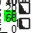

	 	 	 911 cells found after a total of 1000 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 911 cells.
01-Feb-2025 13:28:46: Total of 911 cells are found.
01-Feb-2025 13:28:46: Removing duplicate cells...
01-Feb-2025 13:28:46: 911 cells were retained after removing duplicates.
01-Feb-2025 13:28:46: All done with EXTRACT! 


config.max_iter = 0;
config.visualize_cellfinding = 1;
output = extractor(M,config);

Indeed, as can be seen above, cell finding module is missing several low SNR cells that should have been identified.

### Optimizing the cell finding module

To optimize the cell finding module, we will first note that the earlier run had shown an early cutoff for the trace snr values, indicating that more cells might have been found in lower SNR values. Second, the cellfind min snr value was centered around 5 (often should be ~10-100s), a rather low value. Thus, we first pick very low values for both parameters. 

Next, since our main concern is being able to identify cells, we can also decrease the cutoff value for the spatial lowpass filter. This will allow more smoothing of the movie used for the cell finding purposes only.

01-Feb-2025 13:35:07: Signal extraction will run on 1 partitions serially... 
01-Feb-2025 13:35:07: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 47.3615 
	 	 	 	 minimum magnitude: 17.8540 
			 Step #100, found 100 cells... 
			 Step #200, found 200 cells... 
			 Step #300, found 300 cells... 
			 Step #400, found 400 cells... 
			 Step #500, found 500 cells... 
			 Step #600, found 600 cells... 
			 Step #700, found 700 cells... 
			 Step #800, found 800 cells... 
			 Step #900, found 900 cells... 
			 Step #1000, found 999 cells... 


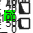

	 	 	 999 cells found after a total of 1000 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 999 cells.
01-Feb-2025 13:41:23: Total of 999 cells are found.
01-Feb-2025 13:41:23: Removing duplicate cells...
01-Feb-2025 13:41:23: 999 cells were retained after removing duplicates.
01-Feb-2025 13:41:23: All done with EXTRACT! 


M = single(h5read("D:\W2_DATA\2025_01_30_GCaMP8s_tdtomato_mk303\mk303_mbo_2umpx_2roi_448umx896um_17p07_green_14planes_00001\matlab\assembled\assembled_plane_7.h5", "/Y"));

config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 0;
config.visualize_cellfinding = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
output = extractor(M,config);

And voila! We have achieved a satisfactory cell finding process, where almost all cells (but also some garbage) are found. The next tutorial will discuss how to optimize the cell refinement module, which primarily aims to cull away the false-positive candidates.